load('C:\Users\Asus\Desktop\data_A')

x=data_noise(1:1000,1:11);
y=data_noise(1:1000,12);
rng('default');
cv = cvpartition(size(x,1),'HoldOut',0.3);
idx = cv.test;
% Separate to training and test data
x_train = x(~idx,:);
x_test  = x(idx,:);
y_train = y(~idx,:);
y_test  = y(idx,:);  

teta=0.5*eye(11,1);
p=100*eye(size(x_train, 2));

for i=1:700
    p = p - (p* x_train(i,:)' * x_train(i,:)*p) /(1+x_train(i,:)*p*x_train(i,:)');
    epsilon = y_train(i)-x_train(i,:)*teta;
    teta = teta + p*x_train(i,:)'*epsilon;
end

% Define initial conditions
P_init = eye(size(x_train, 2));
theta_init = zeros(1, size(x_train, 2));

% Call RLS function with different initial conditions
theta_est_1 = rls1(x_train, y_train, P_init, theta_init);
theta_est_2 = rls1(x_train, y_train, 0.1 * P_init, theta_init);
theta_est_3 = rls1(x_train, y_train, 100000 * P_init, theta_init);


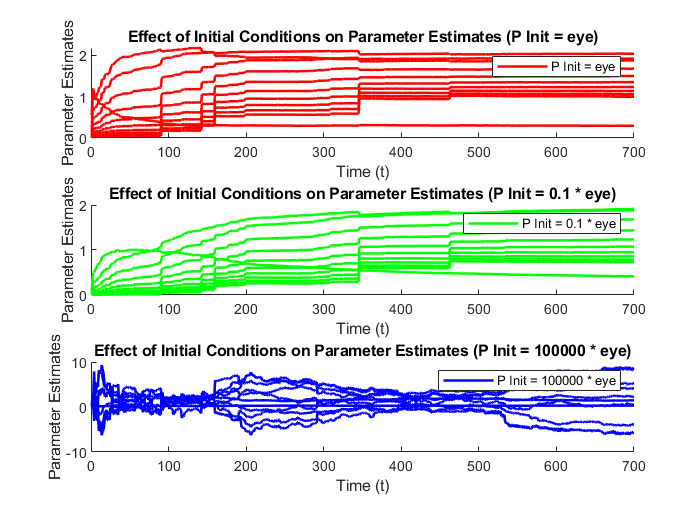

t = 1:size(x_train, 1);

figure;

subplot(3,1,1); % First subplot
hold on;
plot(t, theta_est_1, 'r', 'LineWidth', 1.5);
legend('P Init = eye');
xlabel('Time (t)');
ylabel('Parameter Estimates');
title('Effect of Initial Conditions on Parameter Estimates (P Init = eye)');
hold off;

subplot(3,1,2); % Second subplot
hold on;
plot(t, theta_est_2, 'g', 'LineWidth', 1.5);
legend('P Init = 0.1 * eye');
xlabel('Time (t)');
ylabel('Parameter Estimates');
title('Effect of Initial Conditions on Parameter Estimates (P Init = 0.1 * eye)');
hold off;

subplot(3,1,3); % Third subplot
hold on;
plot(t, theta_est_3, 'b', 'LineWidth', 1.5);
legend('P Init = 100000 * eye');
xlabel('Time (t)');
ylabel('Parameter Estimates');
title('Effect of Initial Conditions on Parameter Estimates (P Init = 100000 * eye)');
hold off;

t = 1:size(x_train, 1);
num_values = 11; 

figure;

for i = 1:num_values
    subplot(num_values, 1, i);
    hold on;
    plot(t, theta_est_1(i, :), 'r', 'LineWidth', 1.5);
    plot(t, theta_est_2(i, :), 'g', 'LineWidth', 1.5);
    plot(t, theta_est_3(i, :), 'b', 'LineWidth', 1.5);
    legend('P Init = eye', 'P Init = 0.1 * eye', 'P Init = 10 * eye');
    xlabel('Time (t)');
    ylabel('Parameter Estimates');
    title(['Effect of Initial Conditions on Parameter Estimates (Value ', num2str(i), ')']);
    hold off;
end


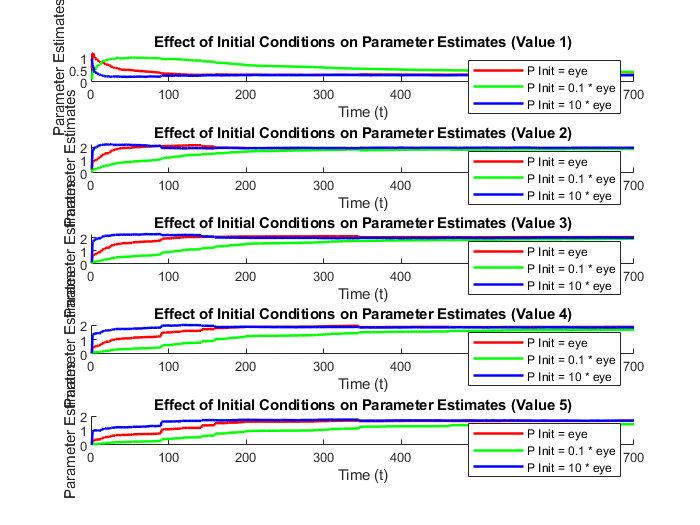

t = 1:size(x_train, 1);
num_values = 5; 

figure;

for i = 1:num_values
    subplot(num_values, 1, i);
    hold on;
    plot(t, theta_est_1(:, i), 'r', 'LineWidth', 1.5);
    plot(t, theta_est_2(:, i), 'g', 'LineWidth', 1.5);
    plot(t, theta_est_3(:, i), 'b', 'LineWidth', 1.5);
    legend('P Init = eye', 'P Init = 0.1 * eye', 'P Init = 10 * eye');
    xlabel('Time (t)');
    ylabel('Parameter Estimates');
    title(['Effect of Initial Conditions on Parameter Estimates (Value ', num2str(i), ')']);
    hold off;
end

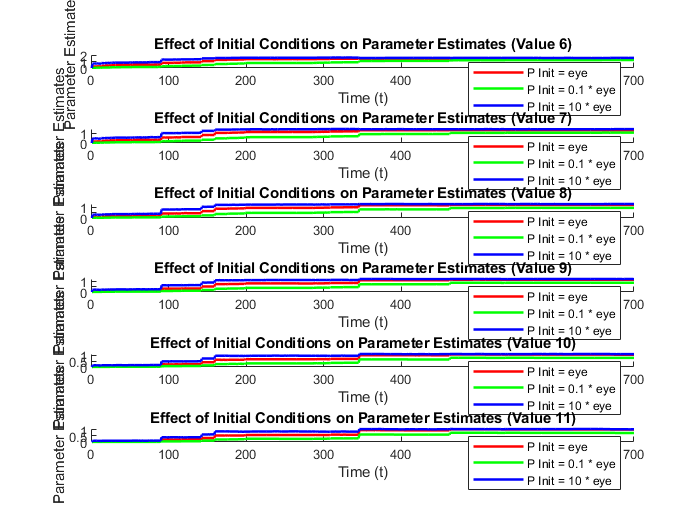

t = 1:size(x_train, 1);
num_values = 11; 
num_values1=6;
figure;
j=1;
for i = 6:num_values
    subplot(num_values1, 1, j);
    hold on;
    plot(t, theta_est_1(:, i), 'r', 'LineWidth', 1.5);
    plot(t, theta_est_2(:, i), 'g', 'LineWidth', 1.5);
    plot(t, theta_est_3(:, i), 'b', 'LineWidth', 1.5);
    legend('P Init = eye', 'P Init = 0.1 * eye', 'P Init = 10 * eye');
    xlabel('Time (t)');
    ylabel('Parameter Estimates');
    title(['Effect of Initial Conditions on Parameter Estimates (Value ', num2str(i), ')']);
    hold off;
    j=j+1;
end


% Define initial conditions
P_init = eye(size(x_train, 2));
theta_init1 = zeros(1, size(x_train, 2));
theta_init2 = 0.5*ones(1, size(x_train, 2));
theta_init3 = 1.5*ones(1, size(x_train, 2));
theta_init4 = 2*ones(1, size(x_train, 2));

% Call RLS function with different initial conditions
theta_est_1 = rls1(x_train, y_train, P_init, theta_init1);
theta_est_2 = rls1(x_train, y_train, P_init, theta_init2);
theta_est_3 = rls1(x_train, y_train,  P_init, theta_init3);
theta_est_4 = rls1(x_train, y_train,  P_init, theta_init4);

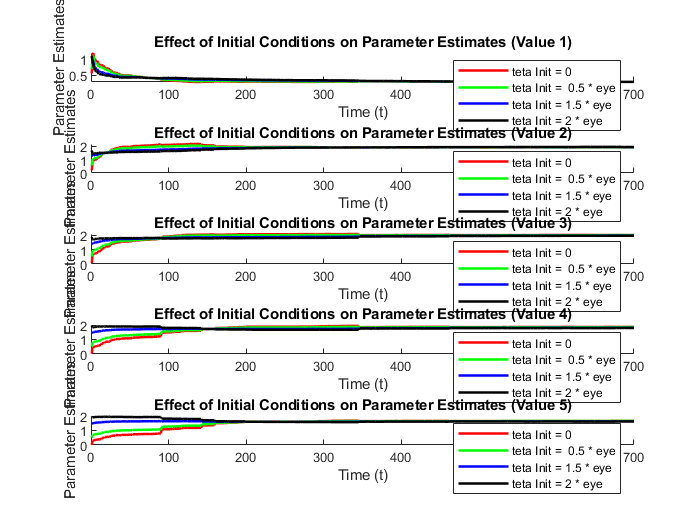

t = 1:size(x_train, 1);
num_values = 5; 

figure;

for i = 1:num_values
    subplot(num_values, 1, i);
    hold on;
    plot(t, theta_est_1(:, i), 'r', 'LineWidth', 1.5);
    plot(t, theta_est_2(:, i), 'g', 'LineWidth', 1.5);
    plot(t, theta_est_3(:, i), 'b', 'LineWidth', 1.5);
    plot(t, theta_est_4(:, i), 'black', 'LineWidth', 1.5);

    legend('teta Init = 0', 'teta Init =  0.5 * eye', 'teta Init = 1.5 * eye', 'teta Init = 2 * eye');
    xlabel('Time (t)');
    ylabel('Parameter Estimates');
    title(['Effect of Initial Conditions on Parameter Estimates (Value ', num2str(i), ')']);
    hold off;
end

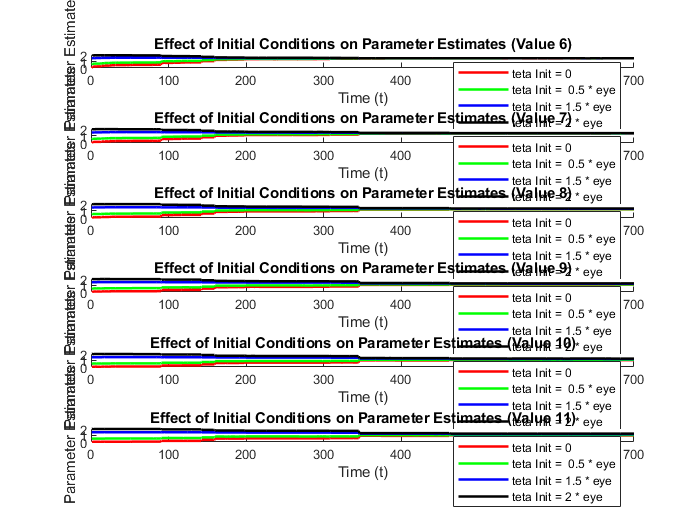

t = 1:size(x_train, 1);
num_values = 11; 
num_values1=6;
figure;
j=1;
for i = 6:num_values
    subplot(num_values1, 1, j);
    hold on;
       plot(t, theta_est_1(:, i), 'r', 'LineWidth', 1.5);
    plot(t, theta_est_2(:, i), 'g', 'LineWidth', 1.5);
    plot(t, theta_est_3(:, i), 'b', 'LineWidth', 1.5);
    plot(t, theta_est_4(:, i), 'black', 'LineWidth', 1.5);

    legend('teta Init = 0', 'teta Init =  0.5 * eye', 'teta Init = 1.5 * eye', 'teta Init = 2 * eye');
    xlabel('Time (t)');
    ylabel('Parameter Estimates');
    title(['Effect of Initial Conditions on Parameter Estimates (Value ', num2str(i), ')']);
    hold off;
    j=j+1;
end

P_init = 10*eye(size(x_train, 2));
theta_init = 0.5*eye(1, size(x_train, 2));

% Call RLS function with different initial conditions
teta_hat = rls1(x_train, y_train, P_init, theta_init);

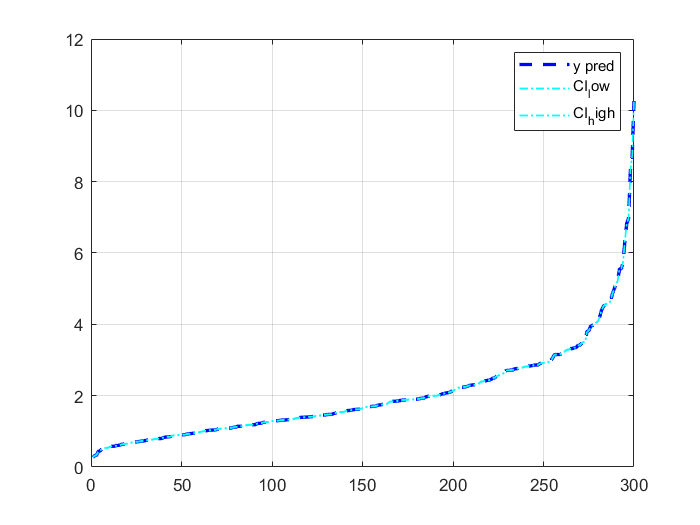

hold off

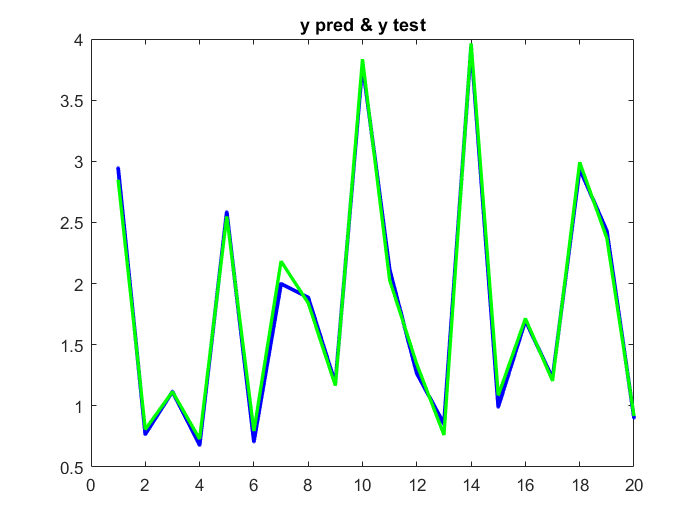

  y_pred_train=x_train*teta;
   y_pred=x_test*teta;
   
   MSE = mean((y_pred - y_test).^2);
   MSE_test = MSE;
   
   MSE1 = mean((y_pred_train - y_train).^2);
   MSE_train = MSE1;
   
   errors =  y_test - y_pred;
   error_test=errors;
   
   errors1 =  y_train - y_pred_train;
   error_train=errors1;
   
   MAE = mean(abs(y_pred - y_test));
   MAE_test = MAE;

   MAE1 = mean((y_pred_train - y_train).^2);
   MAE_train = MAE1;
   
   
% subplot_rows = 3;
% subplot_cols = 4;
% 
%     % Generate the plot for the current i
% subplot(subplot_rows, subplot_cols, i);
u = x_test(:, 2);
cov_teta_hat = ((errors' * errors) * (x_train' * x_train)^-1)/(700-11);
errbar = sqrt(diag(x_test * cov_teta_hat * x_test'));






plot(y_pred(1:20,:),'.-b','linewidth',2.3);
hold on
plot(y_test(1:20,:),'-g','linewidth',2);
title("y pred & y test");
 hold off 

 
%  subplot(subplot_rows, subplot_cols, i);
% plot(y_pred,'.-b','linewidth',2.3);
% hold on
% plot(y_test,'-g','linewidth',2);
% title("y pred & y test");
%  hold off 
%  
 
 
 

ghodrat_noise=errors.'*errors/(700-11);
deghat_takhmin=cov(teta);
deghat_model=MSE;

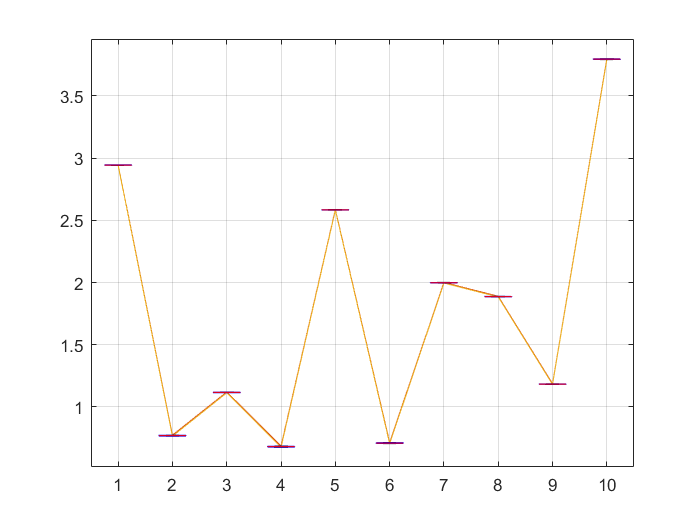

    
u1=1:1:10;
plot((y_pred(1:10,:)),'-');
hold on
plot((y_pred(1:10,:)+errbar(1:10,:)));
hold on
plot((y_pred(1:10,:)-errbar(1:10,:)));
grid

x=sort(u1).';
y=sort(y_pred(1:10,:)).';
data = [((y_pred(1:10,:))-errbar(1:10,:)).'; (y_pred(1:10,:)).'; ((y_pred(1:10,:))+errbar(1:10,:)).'];

% Add a box plot
boxplot(data, 'positions', x, 'widths', 0.5);
hold off

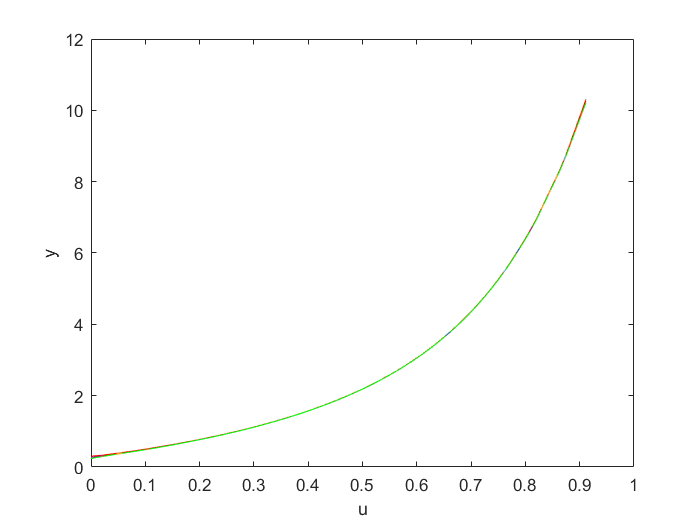

    upper_bound=y_pred + errbar;
    lower_bound=y_pred - errbar;
    
   [a_sorted, sort_idx] = sort(u);
b_sorted = y_pred(sort_idx);
c_sorted =upper_bound(sort_idx);
d_sorted =lower_bound(sort_idx);
% CI_low_sorted=CI_low(sort_idx)
% CI_high_sorted=CI_high(sort_idx)


plot(a_sorted, b_sorted, '-');
hold on;
plot(a_sorted, c_sorted, '-');
hold on
plot(a_sorted, d_sorted, '-');
hold on
% plot(a_sorted, CI_low_sorted, '-');
% hold on
% plot(a_sorted, CI_high_sorted, '-');
% hold on

for j = 1:length(a_sorted)-1
    x = [a_sorted(j), a_sorted(j+1)];
    y = [b_sorted(j), b_sorted(j+1)];
    plot(x, y);
    hold on
    xx = [a_sorted(j), a_sorted(j+1)];
    yy = [c_sorted(j), c_sorted(j+1)];
    plot(xx, yy, 'r--');
     hold on
    xxx = [a_sorted(j), a_sorted(j+1)];
    yyy = [d_sorted(j), d_sorted(j+1)];
    plot(xxx, yyy, 'g--');
%          hold on
%     xxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyy = [CI_low_sorted(j), CI_low_sorted(j+1)];
%     plot(xxxx, yyyy, 'g--');
%          hold on
%     xxxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyyy = [CI_high_sorted(j), CI_high_sorted(j+1)];
%     plot(xxxxx, yyyyy, 'g--');
end
    xlabel('u');
    ylabel('y');


    % Set subplot title

    hold off

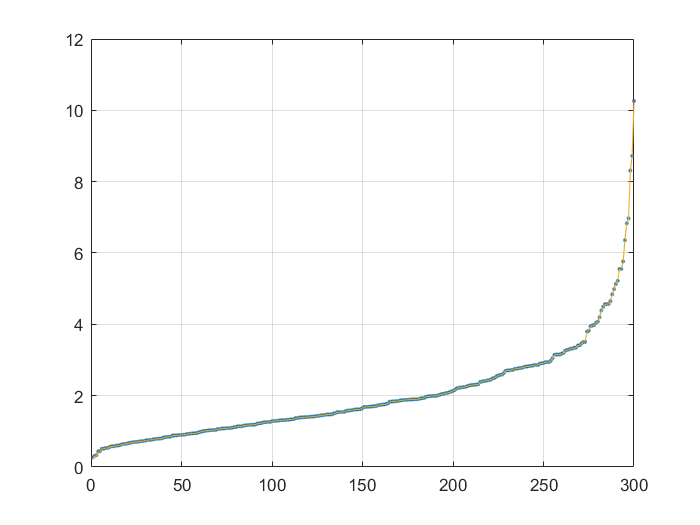

figure;
plot(sort(y_pred),'.');
hold on
plot(sort(y_pred+errbar));
hold on
plot(sort(y_pred-errbar));
grid

% Calculate the confidence interval
CI = 1.96 * std(errors) / sqrt(length(errors));
CI_low = y_pred - CI;
CI_high = y_pred + CI;

% Plot 
figure
plot(sort(y_pred), '--b', 'LineWidth', 2)
hold on
plot(sort(CI_low), '-.c', 'LineWidth', 1)
hold on
plot(sort(CI_high), '-.c', 'LineWidth', 1)
grid
legend('y pred', 'CI_low', 'CI_high')
hold off

teta=zeros(11,1);
% p=0.1*eye(size(x_train, 2));
% p=1*eye(size(x_train, 2));
p=100*eye(size(x_train, 2));

for i=1:700
    p = p - (p* x_train(i,:)' * x_train(i,:)*p) /(1+x_train(i,:)*p*x_train(i,:)');
    epsilon = y_train(i)-x_train(i,:)*teta;
    teta = teta + p*x_train(i,:)'*epsilon;
end

  y_pred_train=x_train*teta;
   y_pred=x_test*teta;
   
   MSE = mean((y_pred - y_test).^2);
   MSE_test = MSE;
   errors =  y_test - y_pred;
   error_test=errors;
  
u = x_test(:, 2);
cov_teta_hat = ((errors' * errors) * (x_train' * x_train)^-1)/(700-11);
errbar = sqrt(diag(x_test * cov_teta_hat * x_test'));

ghodrat_noise=errors.'*errors/(700-11);
deghat_takhmin=cov(teta);
deghat_model=MSE;

function theta_est = rls1(x_train, y_train, P, theta)

    N = size(x_train, 1);
    theta_est = zeros(N, size(theta, 2));
    for t = 1:N      
        phi = x_train(t, :); 
        y = y_train(t, :);    
        
        k = (P * phi') / (1 + phi * P * phi');
        e = y - phi * theta';

        theta = theta + k' * e;
        P = (P - (k * phi * P));
        theta_est(t, :) = theta;
        
%     p = p - (p* x_train(i,:)' * x_train(i,:)*p) /(1+x_train(i,:)*p*x_train(i,:)');
%     epsilon = y_train(i)-x_train(i,:)*teta;
%     teta = teta + p*x_train(i,:)'*epsilon;
    end
end
